## Wafers production Company

a factory produces wafers.

- **Dataset:** wafers.txt contains data about produced wafers with 3 proportions (**Thickness**, **Length**, and **Width**). 

- To use the dataset, you need to install **FSDA** toolbox.

**Load** and **transform** data 

T = readtable('wafer.txt');

% count of wafers
n = height(T);

% Row names
rnames = "w" + (1:n);
T.Properties.RowNames = rnames; % set row names to table
cnames = T.Properties.VariableNames; % column names

Display few rows of the table

disp(head(T, 5))

          Thickness    Length    Width
          _________    ______    _____

    w1        7          4         3  
    w2        4          1         8  
    w3        6          3         5  
    w4        8          6         1  
    w5        8          5         7  



**Plot** measurements to identify anomalous wafers.

### **Parallel Coordinates plot**

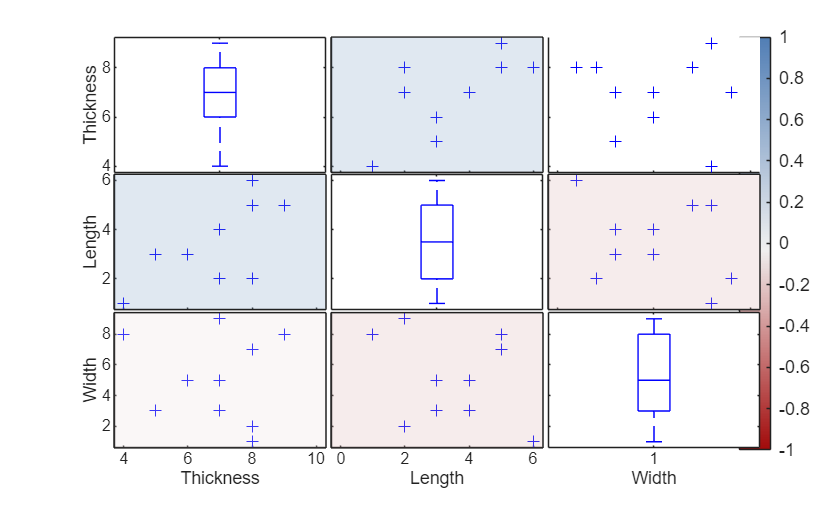

Tt = addvars(T, rnames', 'Before', 1, 'NewVariableNames', 'Wafers');
hold off; % just to prevent frequent errors

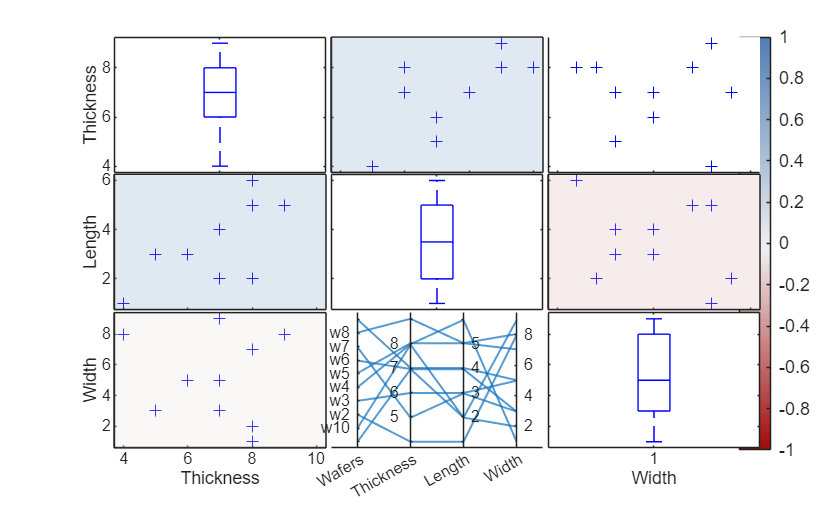

parallelplot(Tt);

**My thoughts:**

However, the plot does not tell a lot about data, but I can see a wafer does not comply with the prescribed proportions. Because, **2 wafers** (6 and 9) have same **Thinkness** and **Length** but different **Widths**. I think, it should not be like this.

### Scatterplot Matrix with Univariate boxplot

% relationship among proportions and correlation matrix
corrMat = corr(T{:, :});
corrMatT = array2table(corrMat, "RowNames",cnames, "VariableNames",cnames);
% Display the correlation matrix (table format)
disp(corrMatT);

                 Thickness     Length      Width  
                 _________    ________    ________

    Thickness           1      0.66866    -0.10131
    Length        0.66866            1    -0.28793
    Width        -0.10131     -0.28793           1



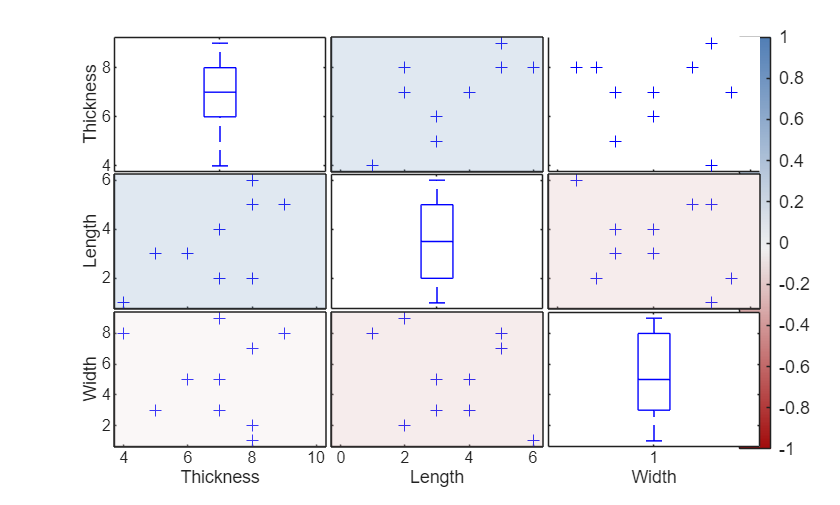


% scatter plot matrix
spmplot(T, "colorBackground",true, "dispopt","box");